# Transmit IQ Samples with ADALM-PLUTO

This script opens a file containing IQ samples "BPSK_IQ_samples_simulation" and transmit them as a waveform with ADALM-PLUTO SDR.

#### PLUTO-SDR Settings

First, we need to establish the configuration parameters for the pluto. 

In this case, the carrier frequency (***fc***) is set to **868 MHz**, which is often used for ISM band applications like IoT devices. And, the transmission gain (***txGain***) is set to **-20 dB**, controlling the output power of the transmitted signal.

fc     = 868e6; % Carrier frequency
txGain = -20;   % Transmit gain (dB)

#### Get IQ samples and data from file

Now, the IQ samples are loaded from the file "**BPSK_IQ_samples_simulation.mat**`"`. The **sampling frequency (*****fs*****)** is retrieved from the file's metadata. A **time vector (*****t*****)** is recreated from the sample indices to visualize the signal over time, and the **IQ data (*****txSamples*****)** contains the actual BPSK-modulated samples that will be transmitted.

load BPSK_IQ_samples_simulation.mat             % Load file containing IQ samples
fs = IQSamples.DataInfo.UserData.fs % Extract sampling frequency

fs = 1000000

t = (IQSamples.Time).*(1/fs);        % Recreat time vector 
txSamples = IQSamples.Data          % Extract IQ samples

txSamples =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


It's important to plot the real part of the IQ samples against the time vector *t* to verify that the signal matches expectations. Therefore, the following plot helps us confirm the integrity of the signal before transmission.

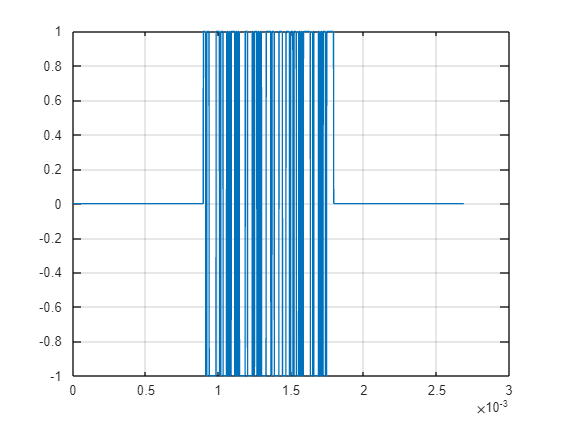

% Plot figure to verify it is as expected
figure
plot (t, real(txSamples))
grid on

#### Open a session on PLUTO-SDR

Once we have all the data prepared for its transmission, we just need to configure and create the transmitter object for the Pluto. 

Firstly, we use a **sdrtx Object **to create a transmitter object (*tx*) to interface with the ADALM-PLUTO SDR. Then as parameters we specify:

- `"`**Pluto**`"`: Specifies the device as a PLUTO SDR.

- `"`**RadioID**`", "`**usb:0**`"`: Specifies the ID of the connected device (e.g., USB port).

- **" BasebandSampleRate"**: Matches the IQ sample rate (**fs**) to ensure proper playback.

- **"CenterFrequency"**: Sets the carrier frequency to **fc**.

- **"Gain"**: Sets the transmission gain (***txGain***).

tx = sdrtx(...
    "Pluto",...
     "RadioID", "usb:0", ...
    "BasebandSampleRate",fs,...
    "CenterFrequency",fc, ...
    "Gain", txGain);

We verify before doing the transmission that both Plutos (for transmission and reception) are properly connected to the computer.

findPlutoRadio

ans = 1×2 struct array with fields:
    RadioID
    SerialNum


#### Use Transmit Repeat function to generate signal continuously

And, we start the transmission. We use the ***transmitRepeat()*** function that sends the IQ samples continuously. This allows the ADALM-PLUTO SDR to loop the provided signal indefinitely without additional input from MATLAB. Therefore, in our application, we are going to do a constant transmission.

transmitRepeat(tx,txSamples)

Now, we are using the first Pluto for transmission, so we need to start receiving with the second Pluto what we are sending. For doing this, we open a new MATLAB instance, and we run there the file "**BPSK_Receiver.mlx**", that is the third and last step of this process. 

#### Stop transmission

The *release* command frees the PLUTO SDR resources. This stops the transmission and disconnects the MATLAB session from the SDR. In this notebook this line of code is commented, so the transmission continues. You can uncomment it when you need to stop the transmitter (because you have already received what you needed with the second Pluto).

%release(tx)

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.
